# Theory 

### ***Describing small-scale structure in random media using pulse-echoultrasound***  

Insana et al. 

[https://pubmed.ncbi.nlm.nih.gov/2299033/](https://pubmed.ncbi.nlm.nih.gov/2299033/)

## Gaussian Model


$$\left(1\right)\;\;\eta {\left(\mathit{\mathbf{f}}\right)}=e^{-0.827{\left(k∙a\right)}^2 } =e^{-0.827{{\left(\frac{2\pi }{c_0 }\right)}}^2 \ ∙\ {a^2 \mathit{\mathbf{f}}}^2 } \to a:\ part\ldotp \ radious$$



$$\left(2\right)\;\eta {\left(\mathit{\mathbf{f}}\right)}=\mathbf{g}\cdot {e^{-\mathit{\mathbf{s}}{\mathit{\mathbf{f}}}^2 } }^{\mathbf{\ }}$$


### Omitting "g" effect, *g=1*

- 
$$\mathit{\mathbf{s}}=0.827{{\left(\frac{2\pi }{c_0 }\right)}}^2 \ \textrm{∙}\ a^2$$


- 
$$a=\sqrt{\frac{\mathit{\mathbf{s}}}{0.827}}\cdot \left(\frac{c_0 }{2\pi }\right)\ {\left[\mu m\right]}$$


- 
$$ka=\sqrt{\frac{\mathit{\mathbf{s}}}{0.827}}\cdot f_{c_{\left\lbrack MHz\right\rbrack } }$$


a2s     = @(a,c0) 0.827 *(2*pi/c0)^2 * a^2;
s2a     = @(s,c0) sqrt(s/0.827)*c0/(2*pi);
s2ka    = @(s,fc) sqrt(s/0.827)*fc;

### Considering "g" effect *(1) == (2)*

- 
$$\ln \left\lbrack g\right\rbrack -s\cdot f^2 =-0.827{{\left(\frac{2\pi }{c_0 }\right)}}^2 \ f^2 \cdot a^2$$



$$\begin{array}{l}
y=A\cdot x\to \hat{x} ={\left(A^T A\right)}^{-1} \cdot \left(A^T y\right)\\
\left\lbrack \ln \left\lbrack g\right\rbrack -sf^2 \right\rbrack =\left\lbrack -0.827{{\left(\frac{2\pi }{c_0 }\right)}}^2 \ f^2 \right\rbrack \cdot \left\lbrack a^2 \right\rbrack 
\end{array}$$



$$a=\sqrt{\hat{x} }$$


## Simulation 1 Gauss

d_g = 0.940154;
dg_dB	= -0.268010;
d_s = 0.022079;


fc = 6; % [MHz]
c0 = 1540; % [m/s]

fMHz = (3:0.1:9)'; % [MHz]
freq = fMHz;

% Reconstruct BSC
bsc_gauss_reconstruct = d_g*exp(-d_s*freq.^2);

%%%%%%%% "ka" no g %%%%%%%%
a_nog = s2a(d_s, c0);
ka_nog = s2ka(d_s, fc);
bsc_nog = exp(-0.827* (2*pi*a_nog/c0)^2 * freq.^2 );


fprintf('-----ka (no g) -----\n')

-----ka (no g) -----


fprintf('a  [µm]      = %.2f\n', a_nog );

a  [µm]      = 40.05


fprintf('ka @ %.2fMHz = %.2f\n', fc, ka_nog );

ka @ 6.00MHz = 0.98




%%%%%%%% "ka" with g %%%%%%%%
yy = log(bsc_gauss_reconstruct);
% yy = log(d_g) - d_s * freq.^2;

AA = -0.827 *(2*pi/c0)^2 * freq.^2;

% x_opt = cgs(AA'*AA, AA'*yy); 
x_opt = AA \ yy;

a_g = sqrt(x_opt);
ka_g = (2*pi*fc/c0)*a_g; 
bsc_g = exp(-0.827* (2*pi*a_g/c0)^2 * freq.^2 );

fprintf('-----ka (with g) -----\n')

-----ka (with g) -----


fprintf('a  [µm]      = %.2f\n', a_g );

a  [µm]      = 41.14


fprintf('ka @ %.2fMHz = %.2f\n', fc, ka_g );

ka @ 6.00MHz = 1.01


## Simulation 1.1 Gauss

d_g = 0.953247;
dg_dB	= -0.207946;
d_s = 0.022739;


fc = 6; % [MHz]
c0 = 1540; % [m/s]

fMHz = (3:0.1:9)'; % [MHz]
freq = fMHz;

% Reconstruct BSC
bsc_gauss_reconstruct = d_g*exp(-d_s*freq.^2);

%%%%%%%% "ka" no g %%%%%%%%
a_nog = s2a(d_s, c0);
ka_nog = s2ka(d_s, fc);
bsc_nog = exp(-0.827* (2*pi*a_nog/c0)^2 * freq.^2 );


fprintf('-----ka (no g) -----\n')

-----ka (no g) -----


fprintf('a  [µm]      = %.2f\n', a_nog );

a  [µm]      = 40.64


fprintf('ka @ %.2fMHz = %.2f\n', fc, ka_nog );

ka @ 6.00MHz = 0.99




%%%%%%%% "ka" with g %%%%%%%%
yy = log(bsc_gauss_reconstruct);
% yy = log(d_g) - d_s * freq.^2;

AA = -0.827 *(2*pi/c0)^2 * freq.^2;

% x_opt = cgs(AA'*AA, AA'*yy); 
x_opt = AA \ yy;

a_g = sqrt(x_opt);
ka_g = (2*pi*fc/c0)*a_g; 
bsc_g = exp(-0.827* (2*pi*a_g/c0)^2 * freq.^2 );

fprintf('-----ka (with g) -----\n')

-----ka (with g) -----


fprintf('a  [µm]      = %.2f\n', a_g );

a  [µm]      = 41.48


fprintf('ka @ %.2fMHz = %.2f\n', fc, ka_g );

ka @ 6.00MHz = 1.02


## Simulation 2 Gauss

d_g = 0.877044

d_g = 0.8770

dg_dB	= -0.569784

dg_dB = -0.5698

d_s = 0.091409

d_s = 0.0914



fc = 6; % [MHz]
c0 = 1540; % [m/s]

fMHz = (3:0.1:9)'; % [MHz]
freq = fMHz;

% Reconstruct BSC
bsc_gauss_reconstruct = d_g*exp(-d_s*freq.^2);

%%%%%%%% "ka" no g %%%%%%%%
a_nog = s2a(d_s, c0);
ka_nog = s2ka(d_s, fc);
bsc_nog = exp(-0.827* (2*pi*a_nog/c0)^2 * freq.^2 );


fprintf('-----ka (no g) -----\n')

-----ka (no g) -----


fprintf('a  [µm]      = %.2f\n', a_nog );

a  [µm]      = 81.485921


fprintf('ka @ %.2fMHz = %.2f\n', fc, ka_nog );

ka @ 6.00MHz = 1.994771




%%%%%%%% "ka" with g %%%%%%%%
yy = log(bsc_gauss_reconstruct);
% yy = log(d_g) - d_s * freq.^2;

AA = -0.827 *(2*pi/c0)^2 * freq.^2;

x_opt = cgs(AA'*AA, AA'*yy); % AA \ yy

cgs converged at iteration 1 to a solution with relative residual 0.



a_g = sqrt(x_opt);
ka_g = (2*pi*fc/c0)*a_g; 
bsc_g = exp(-0.827* (2*pi*a_g/c0)^2 * freq.^2 );

fprintf('-----ka (with g) -----\n')

-----ka (with g) -----


fprintf('a  [µm]      = %.2f\n', a_g );

a  [µm]      = 82.630981


fprintf('ka @ %.2fMHz = %.2f\n', fc, ka_g );

ka @ 6.00MHz = 2.022802


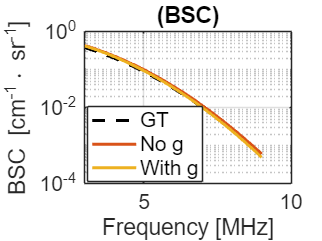


figure, 
font_size = 14;
line_width = 2;
semilogy(freq, bsc_gauss_reconstruct, 'k--', 'LineWidth', line_width,'DisplayName', 'GT')
hold on 
semilogy(freq, bsc_nog, 'LineWidth', line_width, 'DisplayName', 'No g')
semilogy(freq, bsc_g, 'LineWidth', line_width, 'DisplayName', 'With g')
grid on;
xlabel('Frequency [MHz]', 'FontSize', font_size);
ylabel('BSC [cm^{-1}\cdot sr^{-1}]', 'FontSize', font_size);
title('(BSC)', 'FontSize', font_size + 2);
legend('Location', 'best', 'FontSize', font_size);
set(gca, 'FontSize', font_size);

## Effect of $a_{\textrm{eff}}$

% TEST EFFECT ON A RADIOUS

fMHz = (3:0.1:9)'; % [MHz]
freq = fMHz;
c0 = 1540;
bsc_a = @(a,c0,f) exp (-0.827*(2*pi/c0)*f.^2 * a^2 )

a1 = 50; a2=100; a3=0

list_a = [50 75 100 125 150 175 200]

font_size = 14;
line_width = 2;

figure, 
for ii = 1:length(list_a)
a_value =list_a(ii);
semilogy(freq, bsc_a(a_value, c0, freq), '--', 'LineWidth', line_width,'DisplayName', ['a = ', num2str(a_value)])
hold on 
grid on;
xlabel('Frequency [MHz]', 'FontSize', font_size);
ylabel('BSC [cm^{-1}\cdot sr^{-1}]', 'FontSize', font_size);
title('(BSC a_{eff})', 'FontSize', font_size + 2);
legend('Location', 'best', 'FontSize', font_size);
set(gca, 'FontSize', font_size);

end


sigma = sqrt(0.2);
Ts = dx;
t = linspace(-50, 50, N);  % Spatial domain
n = N

n = 1024

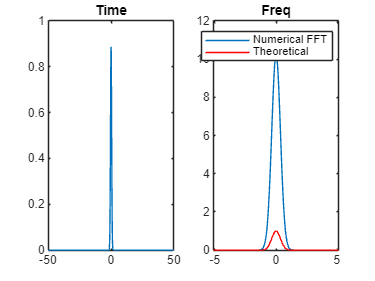

g_t = exp(-t.^2 / (2*sigma^2)) / (sqrt(2*pi)*sigma);

G_f = abs(fftshift(fft(g_t)));
freq = (-n/2:n/2-1)/Ts/n;

G_f_theo = exp(-2*(pi*sigma*freq).^2);

figure, 
subplot(1,2,1)
plot(t, g_t), title('Time')

subplot(1,2,2)
plot(freq, G_f), title('Freq')
hold on;
plot(freq, G_f_theo, 'r');
legend('Numerical FFT', 'Theoretical');

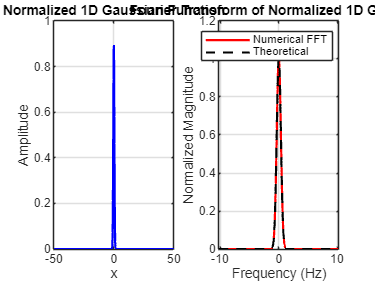

% Clear workspace and close figures
clear; close all; clc;

% Parameters
sigma = sqrt(0.2);           % Standard deviation of the Gaussian
N = 2048;            % Number of points
x = linspace(-50, 50, N);  % Spatial domain

% 1. Create a properly normalized 1D Gaussian Function
g_x = (1 / (sqrt(2 * pi) * sigma)) * exp(-x.^2 / (2 * sigma^2));  % Normalized Gaussian

% 2. Compute the Theoretical Fourier Transform
dx = x(2) - x(1);  % Spatial resolution
f = fftshift(fftfreq(N, dx));  % Frequency axis
G_f_theoretical = exp(-2 * (pi^2) * sigma^2 * f.^2);

% 3. Compute the FFT of the Gaussian Numerically
G_f_numerical = fftshift(fft(g_x));  % Compute FFT
G_f_numerical_magnitude = abs(G_f_numerical);  % Magnitude of FFT

% 4. Plot the Results

% Plot the Gaussian function in the spatial domain
figure;
subplot(1, 2, 1);
plot(x, g_x, 'b', 'LineWidth', 1.5);
title('Normalized 1D Gaussian Function');
xlabel('x');
ylabel('Amplitude');
grid on;

% Plot the Fourier Transform: Theoretical vs Numerical
subplot(1, 2, 2);
plot(f, G_f_numerical_magnitude *dx, 'r', 'LineWidth', 1.5); hold on;
plot(f, G_f_theoretical , 'k--', 'LineWidth', 1.5);
title('Fourier Transform of Normalized 1D Gaussian');
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude');
legend('Numerical FFT', 'Theoretical');
grid on;


% Function to generate frequency axis (equivalent to fftfreq in Python)
function freq = fftfreq(N, d)
    freq = [0:N/2-1, -N/2:-1] / (N*d);
end

aa = fftfreq(N, dx)

aa =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1099    0.1199    0.1299    0.1399    0.1499    0.1599    0.1699    0.1799    0.1899    0.1999    0.2099    0.2199    0.2299    0.2399    0.2499    0.2599    0.2699    0.2799    0.2899    0.2999    0.3098    0.3198    0.3298    0.3398    0.3498    0.3598    0.3698    0.3798    0.3898    0.3998    0.4098    0.4198    0.4298    0.4398    0.4498    0.4598    0.4698    0.4798    0.4898


[Sxx,F] = periodogram(g_x,flattopwin(length(x)),length(x),1/dx,'power');
figure, plot(F,Sxx)